if ~exist('data/chap08', 'dir')
    gunzip('https://github.com/sp-au-mu-nl/SpeechComm/raw/refs/heads/main/data/chap08.zip','data')
    unzip('data/chap08.zip', 'data/chap08/')
    gunzip('http://kotoba.slp.k.hosei.ac.jp/~itou/book/2025/SpeechComm/data/CVSPtrain.tgz','data/')
    untar('data/CVSPtrain', 'data/chap08')
end

プログラム 8.2

vowels = ["a","i","ɯ","e","o"];
CLIP_FOLDER = 'data/chap08/train/mp3/';
tblSegment = readtable('data/chap08/FormantCVTrainShort.csv');
files = unique(tblSegment(:,'Filename'));
FS = 16000;
nFFT = 2^ceil(log2(0.02*FS));
nShift = round(0.01*FS);
nSegment = 0;
nMFCC = 13;
for vidx = 1:length(vowels)
    M{vidx,:} = [];
end
for fidx = 1:height(files)
    mp3File = [CLIP_FOLDER, files{fidx,:}{1}, '.mp3'];
    [data, dFs] = audioread(mp3File);
    data = resample(data, FS, dFs);
    data = filter([1 -.97], 1, data);
    for vidx = 1:length(vowels)
%        segment = strcmp(tblSegment.Filename, files{fidx,:}{1});
        c1 = strcmp(tblSegment.Vowel, vowels(vidx));
        c2 = strcmp(tblSegment.Filename, files{fidx,:}{1});
        segment = tblSegment{c1&c2,["Begin","End"]};
        nSegment = height(segment);

        for sidx = 1:nSegment
            eidx = fix(FS*segment(sidx,2))-1;
            if length(data) < eidx
                eidx = length(data);
            end
            x = data(fix(FS*segment(sidx,1)):eidx);
            if length(x) < 512
                x(512) = 0;
            end
            m = mfcc(x, FS, "Window", hann(nFFT), ...
                "OverlapLength", nFFT-nShift);
            m(:,1) = 0;
            M{vidx,:} = [M{vidx,:}, m'];
        end
    end
end


経過時間は 88.128967 秒です。


GMM = {};
for vidx = 1:length(vowels)
    GMM{vidx} = fitgmdist(M{vidx,:}', 5, ...
        "CovarianceTYpe", "diagonal", ...
        "RegularizationValue", 0.01);
end

プログラム 8.3

figure;
[yAiueo, fs] = audioread('data/chap08/aiueo16k.wav');
yAiueo = filter([1 -.97], 1, yAiueo);
m = mfcc(yAiueo, fs, "Window", hann(nFFT), ...
    "OverlapLength", nFFT-nShift);
m(:,1) = 0;
like = zeros(size(m,1), length(vowels));
for vidx = 1:length(vowels)
    like(:,vidx) = pdf(GMM{vidx},m);
end
yyaxis left
spectrogram(yAiueo, hann(nFFT), nFFT-nShift, nFFT, fs, 'yaxis'); 

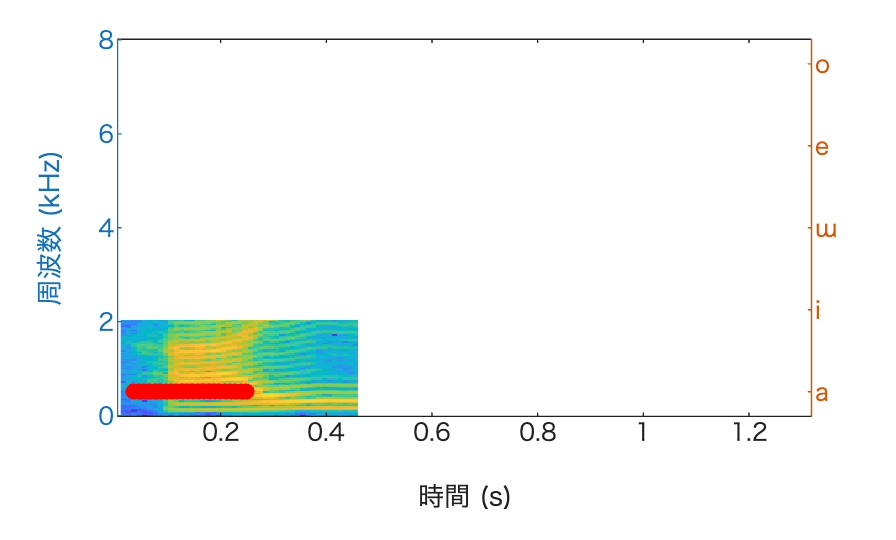

colorbar off;
[~, argmax] = max(like, [], 2);
yyaxis right
t = linspace(0, numel(yAiueo)/fs, size(m,1)+1);
t = t(1:end-1) + nShift/fs/2;
scatter(t, argmax, "filled", "MarkerFaceColor","r");
ylim([0.7 5.3])
yticks(1:5)
yticklabels(vowels)

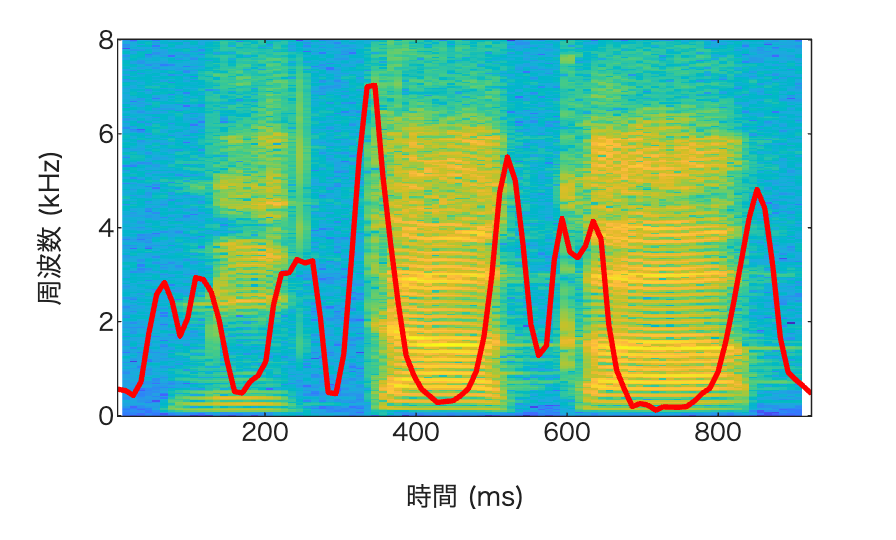

figure;
[yMitaka, sr] = audioread('data/chap08/mitaka48k.wav');
yMitaka = resample(yMitaka, FS, sr);
yMitaka = filter([1 -.97], 1, yMitaka);
nFFT = 512; nShift = 160;
spectrogram(yMitaka, hann(nFFT), nFFT-nShift, nFFT, fs, 'yaxis'); hold on
colorbar off; hold on
m = mfcc(yMitaka, FS, "Window", hann(nFFT), "OverlapLength", nFFT-nShift);
m = m';
x = [ones(5,1) (-2:2)'];
m = [m(:,1) m(:,1) m m(:,end) m(:,end)];
dMFCC = [];
for iColumn = 3:size(m,2)-2
    y = m(:,iColumn-2:iColumn+2);
    b = pinv(x)*y';
    dMFCC = [dMFCC b(2:end,:)'];
end
t = linspace(0, numel(yMitaka)/FS, size(m,2)-3);
t = t(1:end-1) + nShift/fs/2;
plot(t*1000, 2*vecnorm(dMFCC), 'r', 'LineWidth',2); hold off

spectrogram(yMitaka, hann(nFFT), nFFT-nShift, nFFT, fs, 'yaxis'); hold on

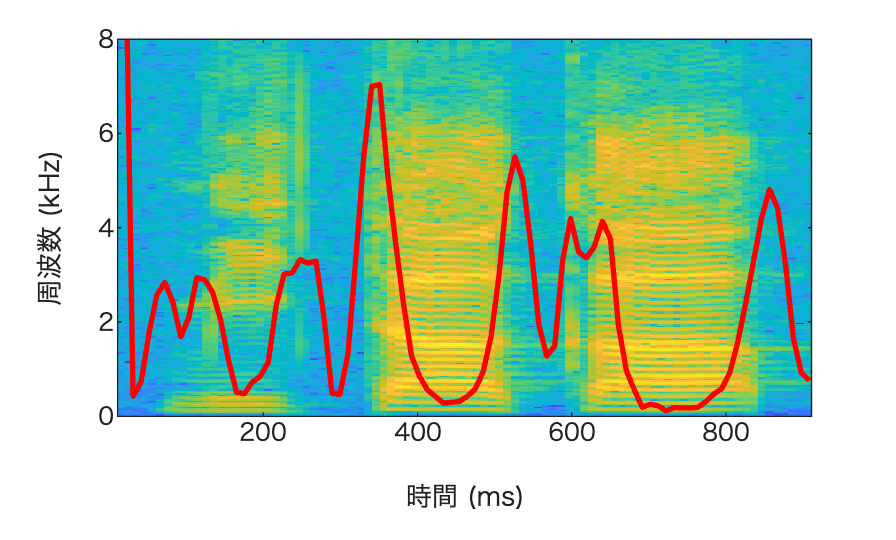

colorbar off; hold on
[~, dMFCC] = mfcc(yMitaka, FS, "Window", hann(nFFT), ...
    "OverlapLength", nFFT-nShift, "DeltaWindowLength", 5);
t = linspace(0, numel(yMitaka)/FS, size(m,2)-3);
t = t(3:end-2);
plot(t*1000, vecnorm(dMFCC(4:end,:)'), 'r', 'LineWidth', 2); 
ylim([0 8]); hold off

[SMitaka, f, t] = stft(yMitaka, FS, "Window", hann(nFFT), ...
    "OverlapLength", nFFT-nShift);
logPower = log(sum(abs(SMitaka).^2,1));
logPower = [logPower(1) logPower(1) logPower logPower(end) logPower(end)];
dLogPower = [];
for idx = 3:length(logPower)-2
    y = logPower(idx-2:idx+2);
    b = pinv(x)*y';
    dLogPower = [dLogPower b(2)];
end